clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Three-step

listOfUncertainties = {[-1,1]};
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end
B = @(i) param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd);

s=tf('s');
param.model.Dwz = 80*eye(4);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0.01*eye(4);

yalmip('clear')

q = cell(param.n);
y = cell(param.n);
%fill in p^-1
for i = 1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
Q_hat = sdpvar(28,28);
Y_hat = [sdpvar(4,28,'full')];
%insert Q into Q_hat
Q_hat(1:12,1:12) = blkdiag(q{:});
%insert Y into y_hat
Y_hat(1:4,1:12) = blkdiag(y{:});
gamma = sdpvar(1);

%constraints
constriants = [];

%Define the lyapunaov constraint for the decoupled system 
Lyap = param.model.A * Q_hat(1:param.n*3,1:param.n*3) + Q_hat(1:param.n*3,1:param.n*3) * param.model.A.' + param.model.B_Bar * Y_hat(1:param.n,1:param.n*3) + Y_hat(1:param.n,1:param.n*3).' * param.model.B_Bar.';
    constriants = [constriants, Lyap <= 0, Q_hat(1:param.n*3,1:param.n*3) >= 0];

%Define the parameters for desired response
A = param.model.A + (0)*eye(12);

A_bar = [param.model.A, param.model.Bw*param.model.Cww, zeros(12,4),zeros(12,4),zeros(12,4);
         zeros(4,12),param.model.Aww, zeros(4),zeros(4),zeros(4);
         param.model.Bwz*param.model.Cz, -param.model.Bwz*param.model.DWref*param.model.Cww, param.model.Awz, -param.model.Bwz*param.model.CWref,zeros(4);
         zeros(4,12),param.model.BWref*param.model.Cww, zeros(4),param.model.AWref,zeros(4);
         zeros(4,12), zeros(4),zeros(4),zeros(4),param.model.AWu]; 

B_bar = @(k) [B(k);
             zeros(4,4);
             zeros(4,4);
             zeros(4,4);
             param.model.BWu];

B_DS = [param.model.Bw*param.model.Dww;
         param.model.Bww;
         -param.model.Bwz*param.model.DWref*param.model.Dww;
         param.model.BWref*param.model.Dww;
         zeros(4,4)];

C1_bar = [param.model.Dwz*param.model.Cz, -param.model.Dwz*param.model.DWref*param.model.Cww, param.model.Cwz,-param.model.Dwz*param.model.CWref,zeros(4);
      zeros(4,12),zeros(4),zeros(4),zeros(4),param.model.CWu];

C2_bar = [zeros(4,4);
      param.model.DWu];

D_Bar = [-param.model.Dwz*param.model.DWref*param.model.Dww;
        zeros(4,4);];

% Step 1-3
constraints = [param.model.A * Q_hat(1:12,1:12) + Q_hat(1:12,1:12) * param.model.A.' + param.model.B_Bar * Y_hat(1:4,1:12) + Y_hat(1:4,1:12).' * param.model.B_Bar.' <=0];
for i=1:length(Uncertainties)
    constraints = [constraints, [Q_hat*A_bar.'+A_bar*Q_hat+Y_hat.'*B_bar(i).'+B_bar(i)*Y_hat, B_DS, Q_hat*C1_bar.'+Y_hat.'*C2_bar.';
                     B_DS.', -gamma*eye(4),D_Bar.';
                     C1_bar*Q_hat+C2_bar*Y_hat, D_Bar, -gamma*eye(8)]<=0];
end
constraints = [constraints,gamma >= 0, Q_hat >=0];

options = sdpsettings('verbose',0,'solver','mosek');
optimize(constraints,[gamma],options);
gammaSF = value(gamma);
y_out = value(Y_hat);
q_out = value(Q_hat);

% step 4
Ksf = y_out(1:4,1:12)/q_out(1:12,1:12);

%step 5
yalmip('clear')
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
gamma = sdpvar(1);
P = sdpvar(28);
P(1:12,1:12) = blkdiag(p{:});
sigma = sdpvar(1);
constraints = [A.'*P(1:12,1:12) + P(1:12,1:12)*A - sigma*(param.model.CySOF.'*param.model.CySOF) <= 0];
for i=1:length(Uncertainties)
    constraints = [constraints, [(A_bar + B_bar(i)*Ksf*[eye(12),zeros(12,16)]).'*P + P*(A_bar + B_bar(i)*Ksf*[eye(12),zeros(12,16)]), P * B_DS, (C1_bar+C2_bar*Ksf*[eye(12),zeros(12,16)]).';
                     B_DS.' * P, -gamma*eye(4),D_Bar.';
                     (C1_bar+C2_bar*Ksf*[eye(12),zeros(12,16)]), D_Bar, -gamma*eye(8)]<=0];
end
constraints = [constraints, P>=0, sigma >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
optimize(constraints, [gamma], options);
gammaSOF_P = value(gamma); 
P_min = value(P);

% Step 6
yalmip('clear')
k = cell(1,param.n);
for j=1:param.n
    k{j} = sdpvar(1,2,'full');
end
K = blkdiag(k{:});
gamma = sdpvar(1);
load('tempP.mat')
    
kvec = [K(:,1);K(:,2);K(:,3);K(:,4);K(:,5);K(:,6);K(:,7);K(:,8)];
constraints = [gamma, kvec.'; kvec, eye(size(kvec,1))]>=0;
% constraints = [constraints, [(A + param.model.B*K*param.model.CySOF).'*Ptest(1:12,1:12) + Ptest(1:12,1:12)*(A + param.model.B*K*param.model.CySOF)]<=0]; 
% constraints = [constraints, [(A + param.model.B*K*param.model.CySOF).'*P_min(1:12,1:12) + P_min(1:12,1:12)*(A + param.model.B*K*param.model.CySOF)]<=0]; 
for i=1:length(Uncertainties)
    % constraints = [constraints, [(A + B(i)*K*param.model.CySOF).'*Ptest(1:12,1:12) + Ptest(1:12,1:12)*(A + B(i)*K*param.model.CySOF)]<=0];
    constraints = [constraints, [(A + B(i)*K*param.model.CySOF).'*P_min(1:12,1:12) + P_min(1:12,1:12)*(A + B(i)*K*param.model.CySOF)]<=0];
end
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, gamma, options);

Ksof = value(K);
Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = Ksof(j,2*(j-1)+1:2*j);
end

% Evaluation of the results from the design procedure
fprintf("Evaluation of design procedure for SOF-FWMM \n")

Evaluation of design procedure for SOF-FWMM 


fprintf("Gamma for SF is found to be: %f \n", value(gammaSF))

Gamma for SF is found to be: 0.003035 


fprintf("Gamma for P SOF is found to be: %f \n", value(gammaSOF_P))

Gamma for P SOF is found to be: 31.741792 


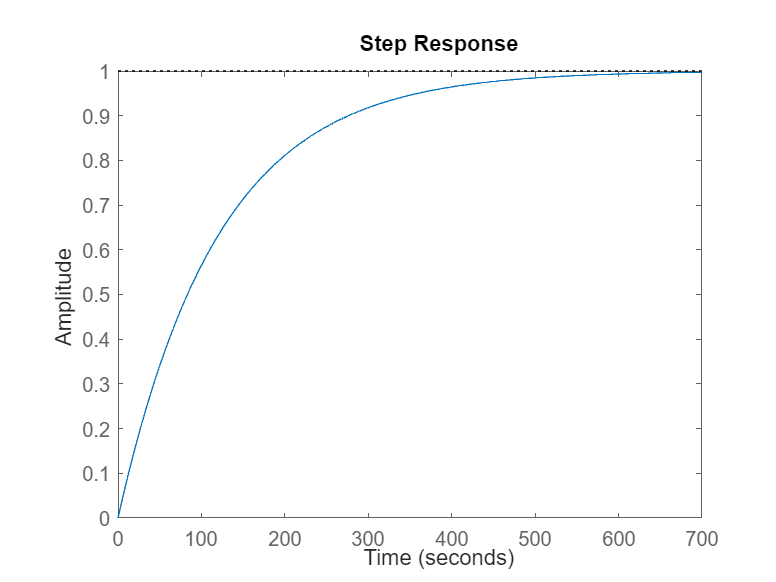


figure()
step(wref(1,1))

param.ctrl.K = Ksf;
fprintf("Step response for the calculated state feedback\n");

Step response for the calculated state feedback


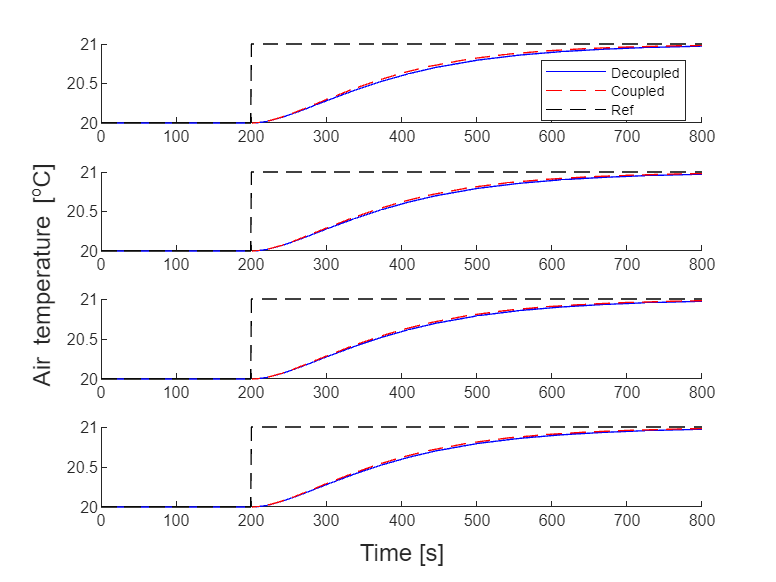

util.SimulateLinearStep(param,"Examination_Output_Feedback_Performance",0,800);

%saves the block version of K this is used further in some simulations
param.ctrl.K = Ksof*param.model.CySOF;
fprintf("Step response for the calculated static output feedback\n");

Step response for the calculated static output feedback


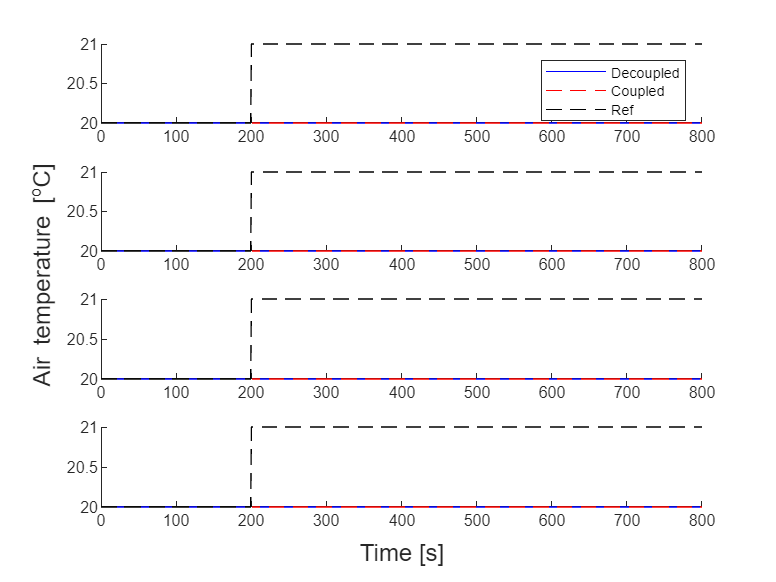

util.SimulateLinearStep(param,"Examination_Output_Feedback_Performance",0,800);


%saves a 3d matrix version of Ks this is used in the simulation of the nonlinear system.
param.ctrl.Ks = Ks;


P_min

P_min = 1.0e+06 *

    0.0920   -0.1202    0.0000         0         0         0         0         0         0         0         0         0   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0002   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.1202    0.1987    0.0004         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0032   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0004    0.0000         0         0         0         0         0         0         0         0         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
         0         0         0    0.1111   -0.1453    0.0000         0         0         0         0         0         0   -0.0000   -0.00

util.CalculatePerformanceLPV(param,{[-1,1]});

Gamma = 80.0000

ans = 1.0e+07 *

   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0838
    0.0843


ans = 1.0e+07 *

    3.7702   -0.0120    0.0000         0         0         0         0         0         0         0         0         0   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0120    0.0844    0.0000         0         0         0         0         0         0         0         0         0   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
         0         0         0    3.6228   -0.0153    0.0000         0         0         0         0         0         0   -0.0000   -0.0006    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0153    0.0844    0.0000         0         0         0         0         0         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.000

P_out = 1.0e+07 *

    3.7702   -0.0120    0.0000         0         0         0         0         0         0         0         0         0   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0120    0.0844    0.0000         0         0         0         0         0         0         0         0         0   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
         0         0         0    3.6228   -0.0153    0.0000         0         0         0         0         0         0   -0.0000   -0.0006    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0153    0.0844    0.0000         0         0         0         0         0         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0